## **All local functions are attached at the end of the script.**

clear all
close all
clc

## 1a) First we load in our ground truth mandible and mandible segmentations from 3 raters

data_dir='C:\Users\reasatt\Data\EECE_395\';
gt = ReadNrrd([data_dir '0522c0001\structures\mandible.nrrd']);
t1 = ReadNrrd([data_dir '\0522c0001\structures\target1.nrrd']);
t2 = ReadNrrd([data_dir '\0522c0001\structures\target2.nrrd']);
t3 = ReadNrrd([data_dir '\0522c0001\structures\target3.nrrd']);

## 1b) Now we create surfaces for all of the volumetric segmentations.

gts = isosurface(gt.data,0.5);
gts.vertices = gts.vertices.*repmat(gt.voxsz,[length(gts.vertices),1]);
t1s = isosurface(t1.data,0.5);
t1s.vertices = t1s.vertices.*repmat(t1.voxsz,[length(t1s.vertices),1]);
t2s = isosurface(t2.data,0.5);
t2s.vertices = t2s.vertices.*repmat(t2.voxsz,[length(t2s.vertices),1]);
t3s = isosurface(t3.data,0.5);
t3s.vertices = t3s.vertices.*repmat(t3.voxsz,[length(t3s.vertices),1]);

## 1c) Display the surfaces in one figure

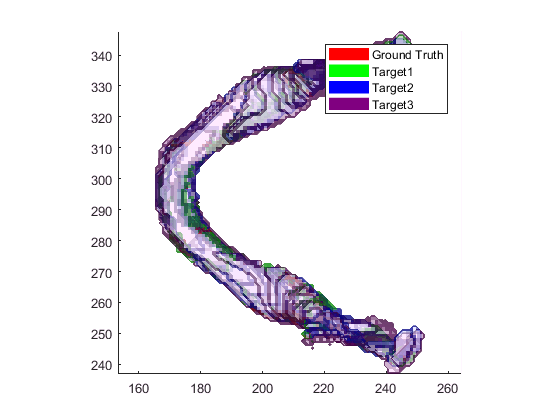

figure(1);clf
DisplayMesh(gts,[1,0,0],0.5);DisplayMesh(t1s,[0,1,0],0.5);DisplayMesh(t2s,[0,0,1],0.5);DisplayMesh(t3s,[0.5,0,0.5],0.5)
legend('Ground Truth', 'Target1','Target2','Target3')

## 1d) Calculate volume

volume_gts=VolumeofMesh(gts);
volume_t1s=VolumeofMesh(t1s);
volume_t2s=VolumeofMesh(t2s);
volume_t3s=VolumeofMesh(t3s);

## 1e) Measure Dice similarity, mean symmetric absolute surface, Hausdorff 

distance between the ground truth and each of the three raters

## Dice

dice_t1=dice(t1.data,gt.data);

dc = 0.9762

dice_t2=dice(t2.data,gt.data);

dc = 0.9737

dice_t3=dice(t3.data,gt.data);

dc = 0.8427

## mean symmetric absolute surface, and Hausdorff distance

[mn1,mn2,mx1,mx2]=SurfaceDistance(gts,t1s);
meandist1=mean([mn1,mn2])

meandist1 = 0.1150

hausdorff1=max([mx1,mx2])

hausdorff1 = 1.1200


[mn1,mn2,mx1,mx2]=SurfaceDistance(gts,t2s);
meandist2=mean([mn1,mn2])

meandist2 = 0.1267

hausdorff2=max([mx1,mx2])

hausdorff2 = 2.3787


[mn1,mn2,mx1,mx2]=SurfaceDistance(gts,t3s);
meandist3=mean([mn1,mn2])

meandist3 = 0.8586

hausdorff3=max([mx1,mx2])

hausdorff3 = 5.2463

## 1g) Create a majority vote segmentation from the three rater segmentations,

measure its volume, and measure Dice similarity, Mean surface, and Hausdorff distances to the ground truth

mv = t1;
mv.data = t1.data + t2.data + t3.data > 1.5;
mvs = isosurface(mv.data,0.5);
mvs.vertices = mvs.vertices.*repmat(mv.voxsz,[length(mvs.vertices),1]);
[mn1,mn2,mx1,mx2]=SurfaceDistance(gts,mvs);
meandistmv=mean([mn1,mn2])

meandistmv = 0.0860

hausdorffmv=max([mx1,mx2])

hausdorffmv = 1.1200

## Functions

function dc=dice(data1,data2)
tp=sum(sum(sum((data1 & data2))));
fp=sum(sum(sum((~data1 & data2))));
%tn=sum(sum(sum((~data1 & ~data2))));
fn=sum(sum(sum((data1 & ~data2))));
dc=2*tp/(2*tp+fp+fn)
end

function [mn1,mn2,mx1,mx2]=SurfaceDistance(gts,t1s)
points=gts.vertices;
dist_gt2t1_min=1000*ones(1,length(points));
% tic
for i=1:length(t1s.faces)
    dist=Points2TriangleDistance(t1s.vertices,t1s.faces(i,:),points);
%     elapsed=toc;
    dist_gt2t1_min(dist_gt2t1_min>dist)=dist(dist_gt2t1_min>dist);
%     if mod(i,500)==0
%         disp(['forward pass eta: ',num2str(elapsed/i*(length(t1s.faces)-i)/60) ' minutes'])
%     end
end

points=t1s.vertices;
dist_t12gt_min=1000*ones(1,length(points));
% tic
for i=1:length(gts.faces)
    dist=Points2TriangleDistance(gts.vertices,gts.faces(i,:),points);
%     elapsed=toc;
    dist_t12gt_min(dist_t12gt_min>dist)=dist(dist_t12gt_min>dist);
%     if mod(i,500)==0
%         disp(['backward pass eta: ',num2str(elapsed/i*(length(gts.faces)-i)/60) ' minutes'])
%     end
end
mn1=mean(dist_gt2t1_min);
mn2=mean(dist_t12gt_min);
mx1=max(dist_gt2t1_min);
mx2=max(dist_t12gt_min);
end

function dist=Points2TriangleDistance(vertices, face,points)

q1=vertices(face(1),:)';
q2=vertices(face(2),:)';
q3=vertices(face(3),:)';
v1=q2-q1; v2=q3-q1;
V=[v1 v2];
coeff=V\(points'-q1);
dist_vect=points'-(q1+V*coeff);
dist=vecnorm(dist_vect);
[m,~]=size(points);
ind_rem=setdiff(1:m,find(coeff(1,:)>=0 & coeff(2,:)>=0 & sum(coeff)<=1));
points_rem=points(ind_rem,:);
v3=q3-q2;

d=v1'*(points_rem'-q1)/vecnorm(v1)^2;
d(d>1)=1; d(d<0)=0;
e=v2'*(points_rem'-q1)/vecnorm(v2)^2;
e(e>1)=1; e(e<0)=0;
f=v3'*(points_rem'-q2)/vecnorm(v3)^2;
f(f>1)=1; f(f<0)=0;

d1=vecnorm(points_rem'-(q1+v1*d));
d2=vecnorm(points_rem'-(q1+v2*e));
d3=vecnorm(points_rem'-(q2+v3*f));
d_vect=[d1;d2;d3];
dist(ind_rem)=min(d_vect);

end


function d=vecnorm(v)
    d=sqrt(sum(v.^2));
end